# **Telco Customer Churn Prediction**

## **A Comparative Study of Logistic Regression and Random Forest**  

**Elnara Mammadova - 210026788**

close all
clear all
clc

ver

-----------------------------------------------------------------------------------------------------
MATLAB Version: 9.10.0.1739362 (R2021a) Update 5
MATLAB License Number: 902060
Operating System: macOS  Version: 11.4 Build: 20F71 
Java Version: Java 1.8.0_202-b08 with Oracle Corporation Java HotSpot(TM) 64-Bit Server VM mixed mode
-----------------------------------------------------------------------------------------------------
MATLAB                                                Version 9.10        (R2021a)
Bioinformatics Toolbox                                Version 4.15.1      (R2021a)
Curve Fitting Toolbox                                 Version 3.5.13      (R2021a)
Deep Learning Toolbox                                 Version 14.2        (R2021a)
Reinforcement Learning Toolbox                        Version 2.0         (R2021a)
Statistics and Machine Learning Toolbox               Version 12.1        (R2021a)


# A. DATA SELECTION

Data preparation and feature engineering for this data was done in Jupyter Notebook. Please refer to the fie in the coursework folder. 

Our original data matrix holds 17 independent and 1 dependent/target variable.

data = readtable('/data/churn_postprocess.csv', 'VariableNamingRule',"preserve");

Predictors:

predictorNames = categorical(data(:, 1:end-1).Properties.VariableNames)

predictorNames = 1×43 categorical array
     ReferredaFriend      NumberofReferrals      Tenure      PhoneService      AvLongDistCharges      MultipleLines      InternetService      AvgGBdownload      OnlineSecurity      OnlineBackup      DeviceProtectionPlan      PremiumTechSupport      StreamingTV      StreamingMovies      StreamingMusic      UnlimitedData      PaperlessBilling      MonthlyCharges      TotalCharges      TotalRefunds      TotalExtraDataCharges      TotalLongDistCharges      TotalRevenue      gender      SeniorCitizen      Partner      Dependents      OfferNone      OfferOfferA      OfferOfferB      OfferOfferC      OfferOfferD      OfferOfferE      InternetTypeCable      InternetTypeDSL      InternetTypeFiberOptic      InternetTypeNone      ContractMonth-to-Month      ContractOneYear      ContractTwoYear      PaymentMethodBankWithdrawal      PaymentMethodCreditCard      PaymentMethodMailedCheck 

Statistical summary of each variable

format compact
summary(data)

Variables:
    ReferredaFriend: 7043×1 double
        Values:
            Min          0    
            Median       0    
            Max          1    
    NumberofReferrals: 7043×1 double
        Values:
            Min       -0.65041
            Median    -0.65041
            Max         3.0151
    Tenure: 7043×1 double
        Values:
            Min         -1.279
            Median    -0.13801
            Max         1.6142
    PhoneService: 7043×1 double
        Values:
            Min          0    
            Median       1    
            Max          1    
    AvLongDistCharges: 7043×1 double
        Values:
            Min          -1.4863
            Median    -0.0044639
            Max           1.7499
    MultipleLines: 7043×1 double
        Values:
            Min          0    
            Median       0    
            Max          1    
    InternetService

X = (data(:, 1:end-1));
y = table2array(data(:, end));
tabulate(y)

  Value    Count   Percent
      0     5174     73.46%
      1     1869     26.54%


# B. DATA PARTITIONING

We addressed the oversampling problem by using SMOTE on the training set alone, after splitting our data into train and test set using 90:10 ratio in Python (refer to the notebook in the coursework file). We also extracted validation set from unbalanced training data (80:20 ratio) to use during validation. 

training = readtable('data/train_balanced.csv','VariableNamingRule',"preserve");
training_unbalanced = readtable('data/train.csv','VariableNamingRule',"preserve");
testing = readtable('/data/test.csv','VariableNamingRule',"preserve");

Partition our data into train, test and validation sets, and their corresponding predictive and response variables:

% train set
X_train = table2array(training(:, 1:end-1));
y_train = table2array(training(:, end));
% train set - unbalanced
X_train_unbalanced = table2array(training_unbalanced(:, 1:end-1));
y_train_unbalanced = table2array(training_unbalanced(:, end));
% test set
X_test = table2array(testing(:, 1:end-1));
y_test = table2array(testing(:, end));

Lets look at count of classes present in the training set before and after oversampling the minority class (0) in train set:

tabulate(y_train_unbalanced)

  Value    Count   Percent
      0     4139     73.46%
      1     1495     26.54%


tabulate(y_train)

  Value    Count   Percent
      0     4139     50.00%
      1     4139     50.00%


Let's look at the count of classes present in the test set where SMOTE was not performed (unbalanced data):

tabulate(y_test)

  Value    Count   Percent
      0     1035     73.46%
      1      374     26.54%


# C. Logistic Regression

A Logistic Regression model is a good model for demonstration because the predicted probabilities are well-calibrated, as opposed to other machine learning models that are not developed around a probabilistic model,

### **C.1. Cross-Validated Lasso Regularization**

Construct a cross-validated lasso regularization of a generalized linear model using 25 Lambda (number of regularizaton coefficients)  on the balanced training data. To determine a good lasso-penalty strength for a linear classification model that uses a logistic regression learner, implement 10-fold cross-validation. Each column of `B` corresponds to a particular regularization coefficient in `Lambda.`

tic
rng('default') % for reproducibility
[B,FitInfo] = lassoglm(X_train,y_train,'binomial',...
    'NumLambda',25, 'CV',10);
toc

Elapsed time is 106.233113 seconds.


### C.2. Cross-Validated Deviance of Lasso Fit

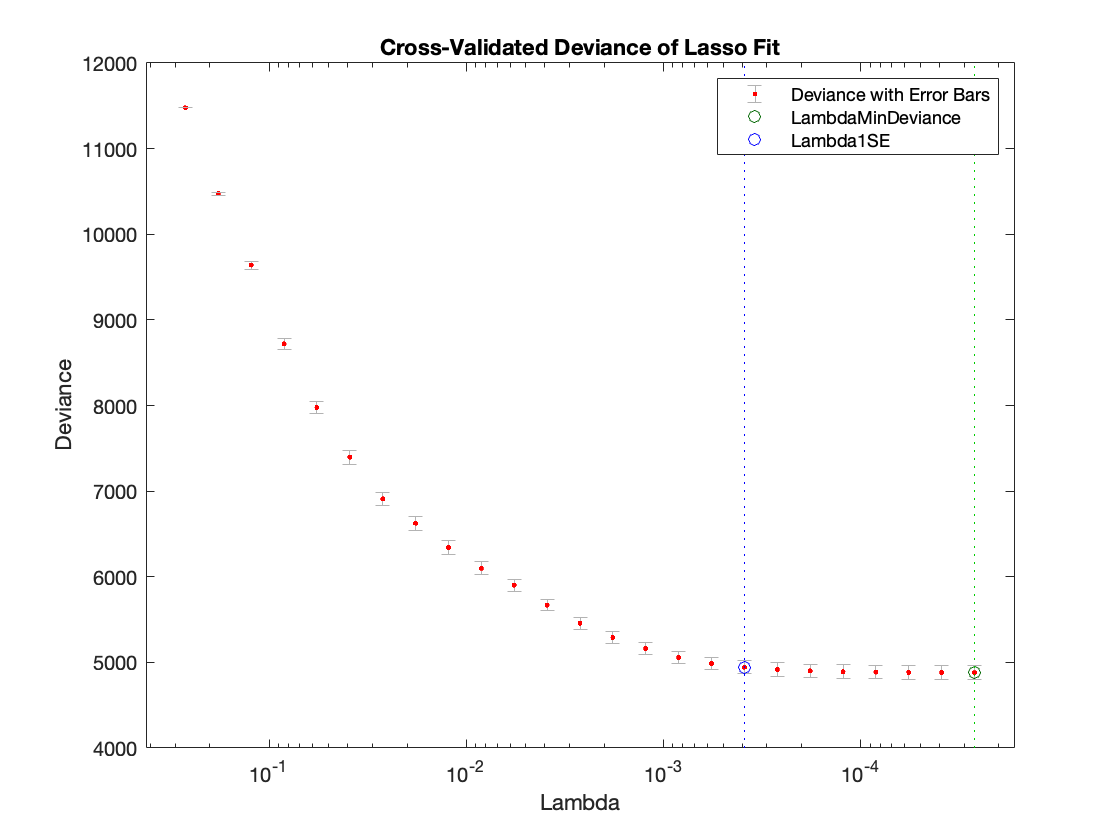

figure;
lassoPlot(B,FitInfo,'PlotType','CV');    
legend('show')

The green circle and dotted line locate the `Lambda` with minimum cross-validation error. Plot identifies the minimum-deviance point as a function of regularization parameter Lambda (25). The blue circle and dotted line locate the point with minimum cross-validation error plus one standard deviation. *The minimum deviance is around ~5000. *

As `Lambda` increases (toward the left), Deviance increases rapidly. The coefficients aren't reduced too much and they adequately fit the responses. As `Lambda` decreases, the models are small (have less nonzero coefficients). 

### **C.3. Trace Plot of Coefficients Fit by Lasso**

Nonzero model coefficients as a function of the regularization parameter Lambda. 

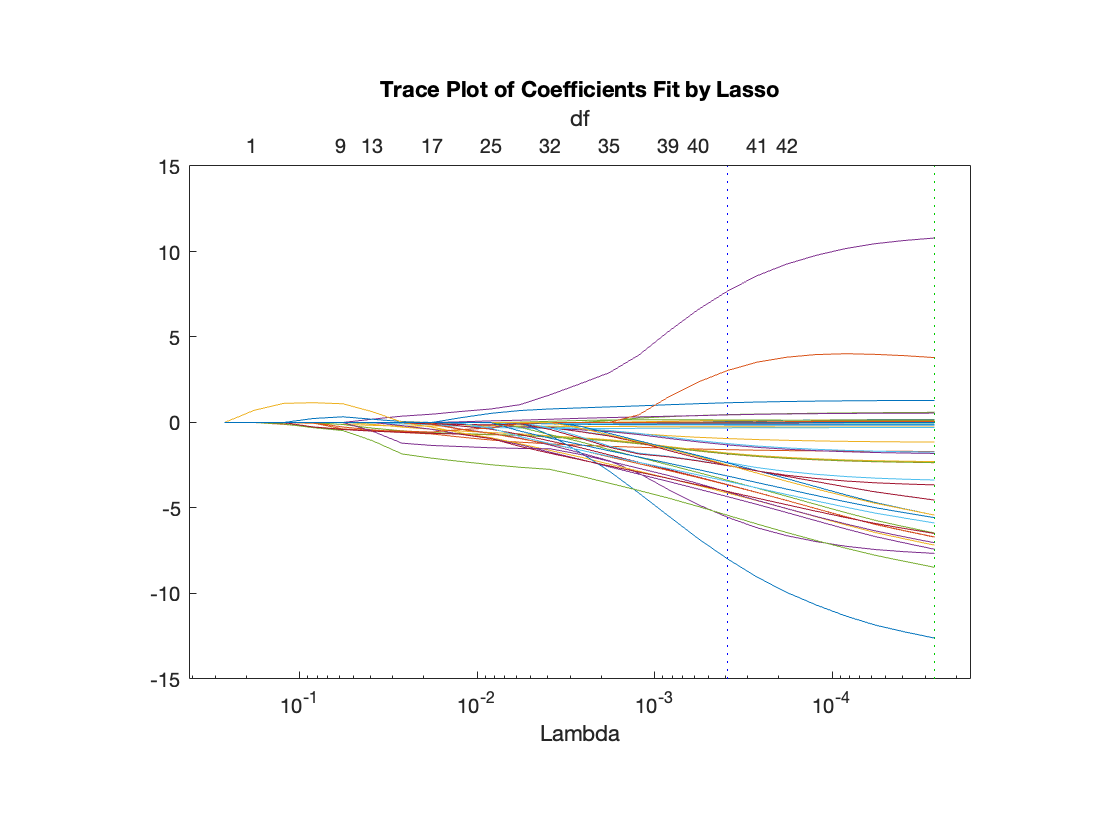

% Plot the fits with the Lambda plot type and logarithmic scaling.
figure;
lassoPlot(B,FitInfo,'PlotType','Lambda','XScale','log');

`lassoPlot` creates the *x*-axis from the `Lambda` field of `FitInfo`. The *x*-axis at the top of the plot contains the degrees of freedom (`df`), meaning the number of nonzero coefficients of `B`. As `Lambda` increases toward the left side of the plot, fewer nonzero coefficients remain. This suggests that the models are not overfitted.

% Display the suggested value of Lambda .
FitInfo.Lambda1SE

ans = 3.9000e-04

% Display the Lambda with minimal MSE.
FitInfo.LambdaMinDeviance

ans = 2.6570e-05

### **C.4. Remove Redundant Predictors by Using Cross-Validated Fits**

Assume the values in `y` are binomially distributed. Choose model coefficients corresponding to the `Lambda` with minimum expected deviance. Find the nonzero model coefficients corresponding to the two identified points in cross-validated deviance of lasso fit:

idxLambdaMinDeviance = FitInfo.IndexMinDeviance;
B0 = FitInfo.Intercept(idxLambdaMinDeviance);
coef = [B0; B(:,idxLambdaMinDeviance)];

Find the nonzero model coefficients corresponding to the second identified points. The coefficients from the minimum-plus-one standard error point below are exactly those coefficients used to create the data: 

idxLambda1SE = FitInfo.Index1SE;
min1coefs = (B(:,idxLambda1SE));
nonzeros = sum(min1coefs ~= 0) % 41 coefficients - nonzero predictors

nonzeros = 40

nonzeroIdx = find(min1coefs) % find indices of nonzero predictors

nonzeroIdx =      1
     2
     3
     4
     6
     7
     8
     9
    10
    11


cnst = FitInfo.Intercept(idxLambda1SE);
B1 = [cnst;min1coefs];

Plot residuals from '`lassoglm`' model

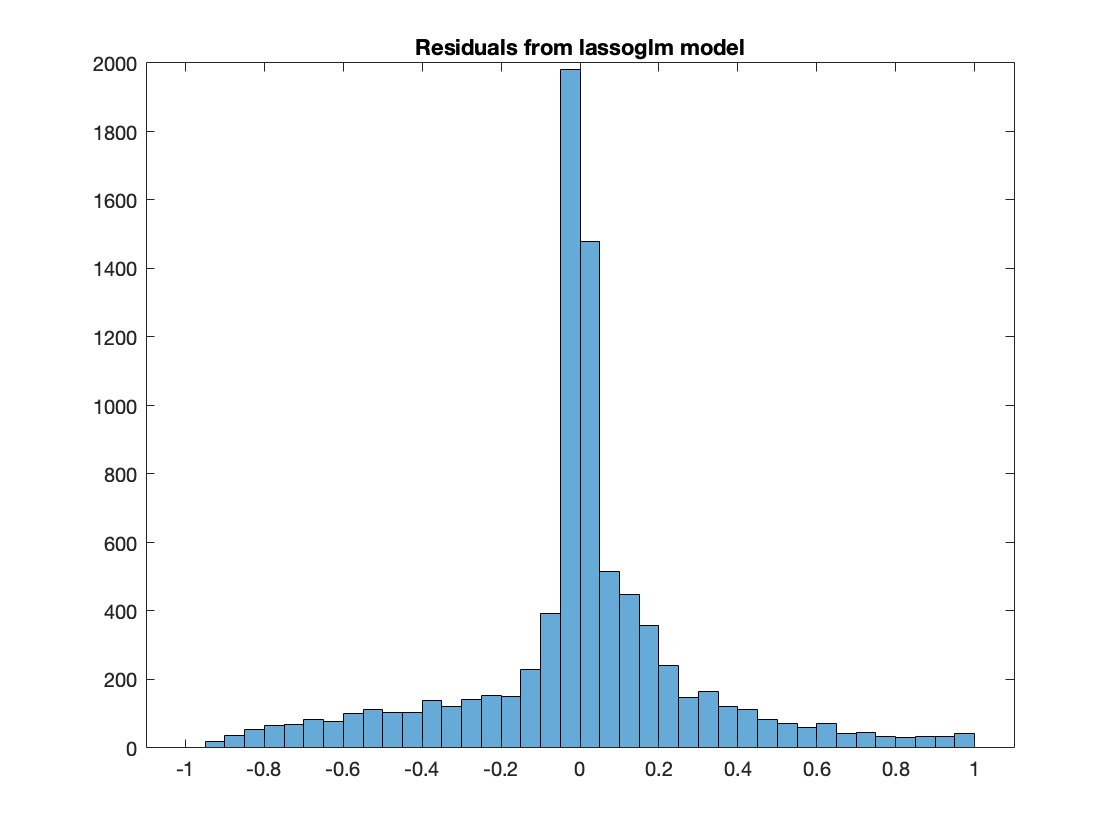

figure;
preds = glmval(B1,X_train,'logit');
histogram(y_train - preds) 
title('Residuals from lassoglm model')

### C.5. Train the model

Fit a logistic binomial model (number of "successes" vs. number of "failures") using the coefficients from the minimum-plus-one standard error point.

tic
LRmdl = fitglm(X_train,y_train,'linear',...
    'Distribution','binomial','PredictorVars',nonzeroIdx)

LRmdl = Generalized linear regression model:
    logit(y) ~ 1 + x1 + x2 + x3 + x4 + x6 + x7 + x8 + x9 + x10 + x11 + x12 + x13 + x14 + x15 + x16 + x17 + x18 + x19 + x20 + x23 + x24 + x25 + x26 + x27 + x28 + x29 + x30 + x31 + x32 + x33 + x34 + x35 + x36 + x37 + x38 + x39 + x40 + x41 + x42 + x43
    Distribution = Binomial

Estimated Coefficients:
                   Estimate         SE           tStat         pValue  
                   _________    __________    ___________    __________
    (Intercept)       138.47    1.5358e+07     9.0166e-06       0.99999
    x1                1.3087       0.25265         5.1798    2.2214e-07
    x2               -1.7025       0.10914        -15.599    7.3887e-55
    x3               -1.1706       0.16781        -6.9756     3.045e-12
    x4   

toc

Elapsed time is 1.337316 seconds.


**p-value = 0

***Plot residuals from linear regression model***

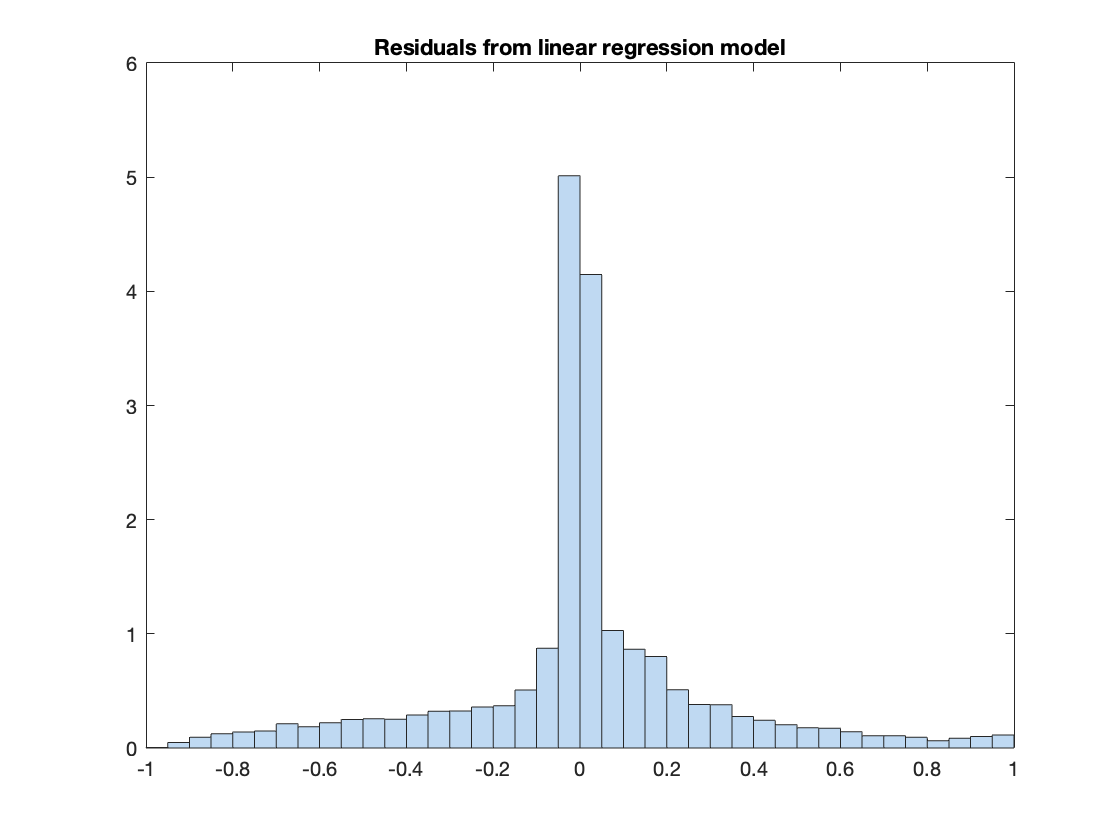

figure;
plotResiduals(LRmdl)
title('Residuals from linear regression model')

Our residuals are slightly right skewed but otherwise pretty symmetrically distributed, tending to cluster towards the middle of the plot. Residuals from Lasso regularized model is the same concentration in the middle as logistic regression, but significantly higher. 

### C.6. Predict responses for feature data in the train data.

The threshold is applied to the cut-off point in probability between the positive and negative classes, which by default for any classifier would be set at 0.5, halfway between each outcome (0 and 1). However we will be setting it to 0.4, in order to bias the predictive behavior of a classification model. That way we will produced imbalanced binary prediction that is not biased to the majority class. 

[LRpredYtrain_,LRpredYtrainScore] = predict(LRmdl,X_train);
LRpredYtrain = double(LRpredYtrain_>=0.4);  

Determine the accuracy of the predictions using a confusion matrix.

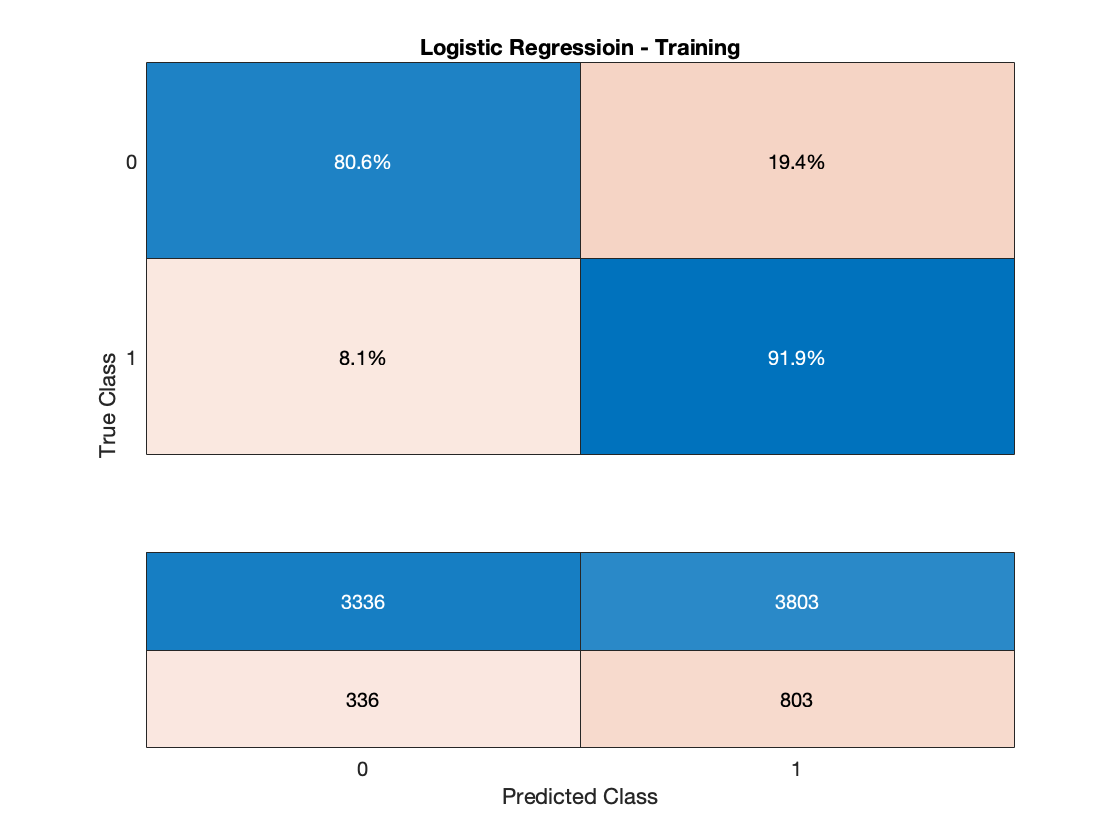

figure;
confusionchart(y_train,LRpredYtrain, 'Normalization',"row-normalized", ...
    'ColumnSummary',"absolute",...
    "Title",'Logistic Regressioin - Training');

cm = confusionmat(y_train,LRpredYtrain)

cm =         3336         803
         336        3803


% Accuracy
LRacc04 = (cm(1,1)+cm(2,2))/(cm(1,1)+cm(2,2)+cm(1,2)+cm(2,1));
% LRacc05 = (cm(1,1)+cm(2,2))/(cm(1,1)+cm(2,2)+cm(1,2)+cm(2,1));

% Recall = TP/(FN+TP)
LRrec04 = cm(2,2)/(cm(2,1)+cm(2,2)); 
% LRrec05 = cm(2,2)/(cm(2,1)+cm(2,2)); 

% Precision = TP/(TN+TP)
LRpre04 = cm(2,2)/(cm(1,2)+cm(2,2)); 
% LRpre05 = cm(2,2)/(cm(1,2)+cm(2,2)); 

% f1 score
LRf104  = 2/(1/LRpre04+1/LRrec04);
% LRf105  = 2/(1/LRpre05+1/LRrec05);

% f2 score
LRf204 = (5*LRpre04*LRrec04)/(4*LRpre04+LRrec04); 
% LRf205 = (5*LRpre05*LRrec05)/(4*LRpre05+LRrec05);

Compare performance measure between threshold 0.4 and 0.5. 

%  modelName = {'LR=0.4 threshold', 'LR=0.5 threshold'};
%  performanceMeasures = {'Accuracy', 'Recall', 'Precision','f1-score','f2-score'};
%  res = [LRacc04,LRacc05;
%         LRrec04,LRrec05;
%         LRpre04,LRpre05;
%         LRf104,LRf105;
%         LRf204, LRf205];
% restable= array2table(res,'RowNames',performanceMeasures,'VariableNames',modelName);
% disp(restable);

                 LR=0.4 threshold    LR=0.5 threshold
                 ________________    ________________
    Accuracy         0.86241             0.87026     
    Recall           0.91882             0.88379     
    Precision        0.82566              0.8605     
    f1-score         0.86975             0.87199     
    f2-score         0.89854             0.87903     


Since our dataset is imbalanced, Recall and F2 scores are more important for our predictions. Getting lower false negatives (predicting churned customer as non-churn is more costly) will result in better accuracy measures. 

### C.7. Feature importance

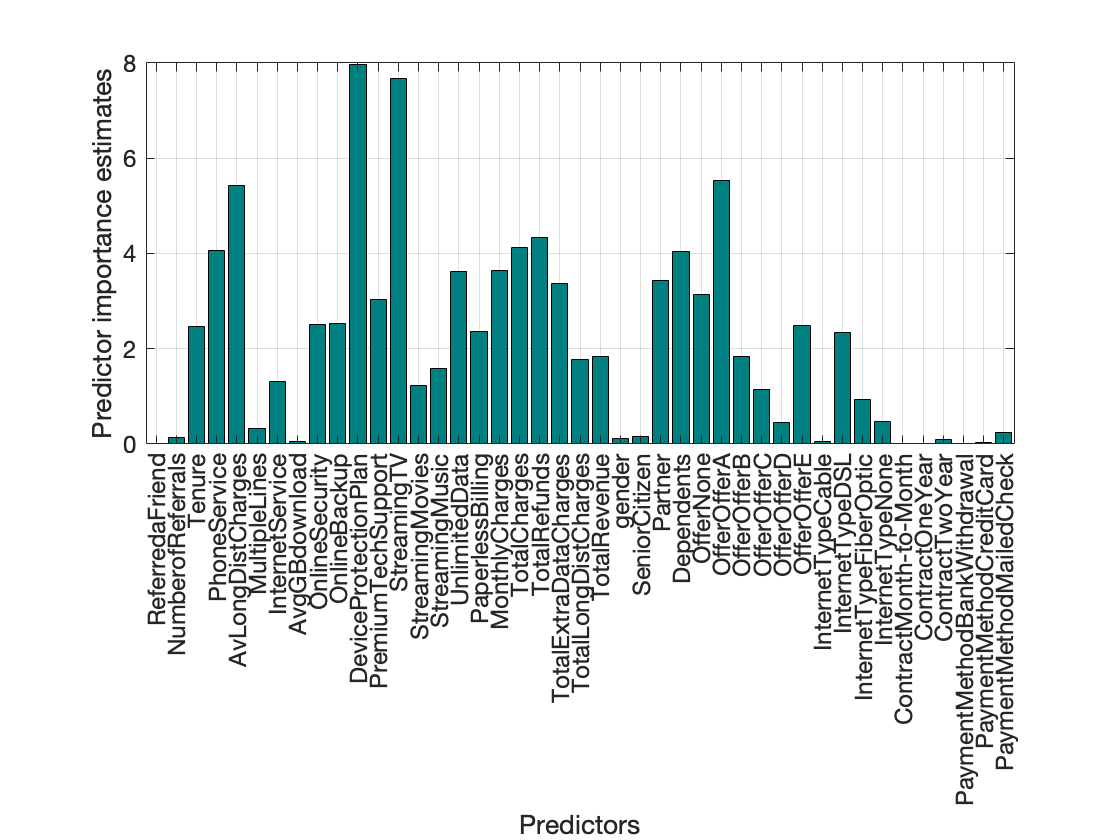

figure;
Xnames = categorical(training(:, 1:end-1).Properties.VariableNames);
abs_coef = abs(B(:,idxLambda1SE));
bar(Xnames,abs_coef, 'FaceColor',[0 .5 .5], ...
    'EdgeColor',[0 0 0],'LineWidth',.5);
ylabel('Predictor importance estimates');
xlabel('Predictors');
set(gca,'xticklabel',Xnames, 'XTickLabelRotation', 90)
ax=gca;
ax.FontSize=12;
grid on

`DeviceProtectionPlan, StreamingTV `and` OfferA` have the highest importance amongst all other predictors. `ReferedAfriend`, `Contracts` and `PaymentMethodBankWithdrowal` and `PaymentMethodCredictCard` are the least important predictors. 

### C.8. Test the model

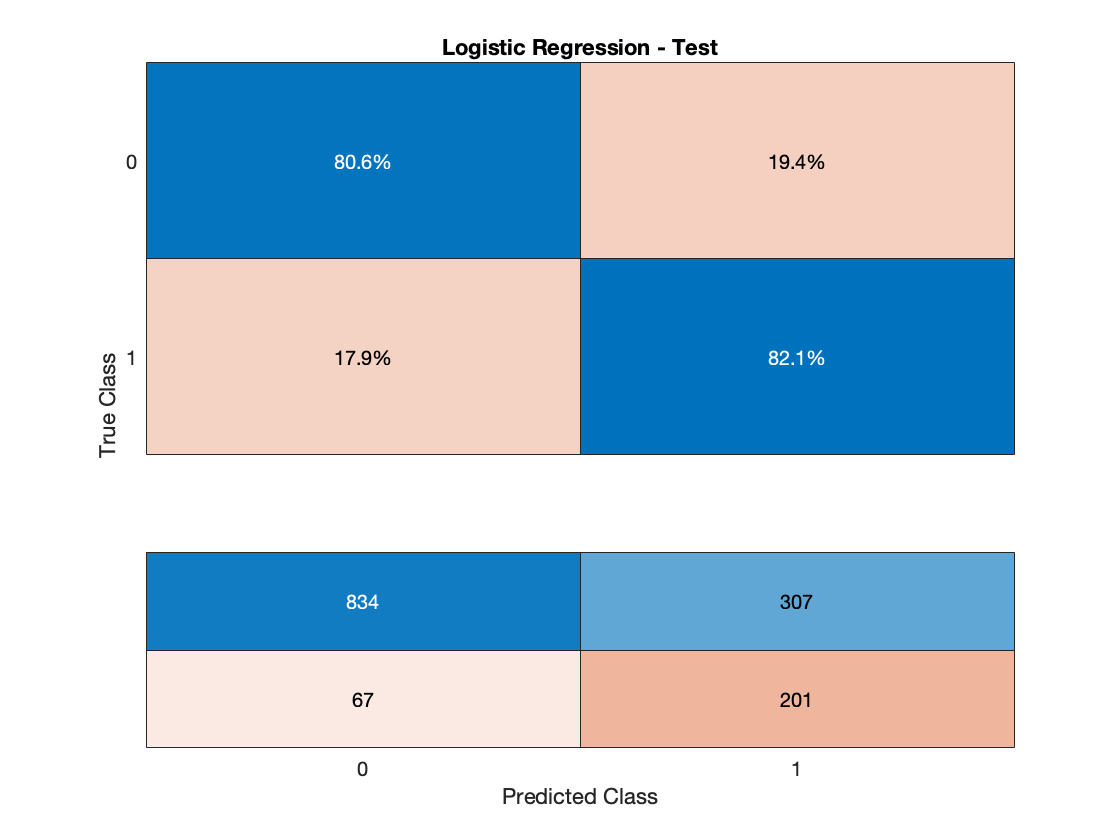

[LRpredYtest_,LRpredYtestScore] = predict(LRmdl,X_test);
LRpredYtest = double(LRpredYtest_>=0.4);
figure;
confusionchart(y_test,LRpredYtest, "Normalization","row-normalized", ...
    'ColumnSummary',"absolute",...
    "Title",'Logistic Regression - Test');

                           Predicted Class 1      Predicted Class 2

True Class 1                  TN                            FP

True Class 2                  FN                            TP

LRconfMat = confusionmat(y_test,LRpredYtest)

LRconfMat =    834   201
    67   307


**i. Threshhold Metrics**

% Accuracy = (TP+TN)/(TP+TN+FP+FN)
LRacc = (LRconfMat(1,1)+LRconfMat(2,2))/sum(sum(LRconfMat)) 

LRacc = 0.8098

% Sensitivity/Recall = TP/(FN+TP)
LRsen = LRconfMat(2,2)/(LRconfMat(2,1)+LRconfMat(2,2)) 

LRsen = 0.8209

% Specificity(True Negative Rate) = TN/(TN+FP)
LRspe = LRconfMat(1,1)/(LRconfMat(1,1)+LRconfMat(1,2))

LRspe = 0.8058

% Precision = TP/(TN+TP)
LRpre = LRconfMat(2,2)/(LRconfMat(1,2)+LRconfMat(2,2))     

LRpre = 0.6043

% f1 score
LRf1  = 2/(1/LRpre + 1/LRsen)

LRf1 = 0.6961

% f2 score
LRf2 = (5*LRpre*LRsen)/(4*LRpre+LRsen) % false negatives are more important (predicting churned customer as non-churn is more costly)

LRf2 = 0.7660

% G-Mean
LRgmean = sqrt(LRsen * LRspe)

LRgmean = 0.8133

**ii. Ranking Metrics**

*ROC and AUC*

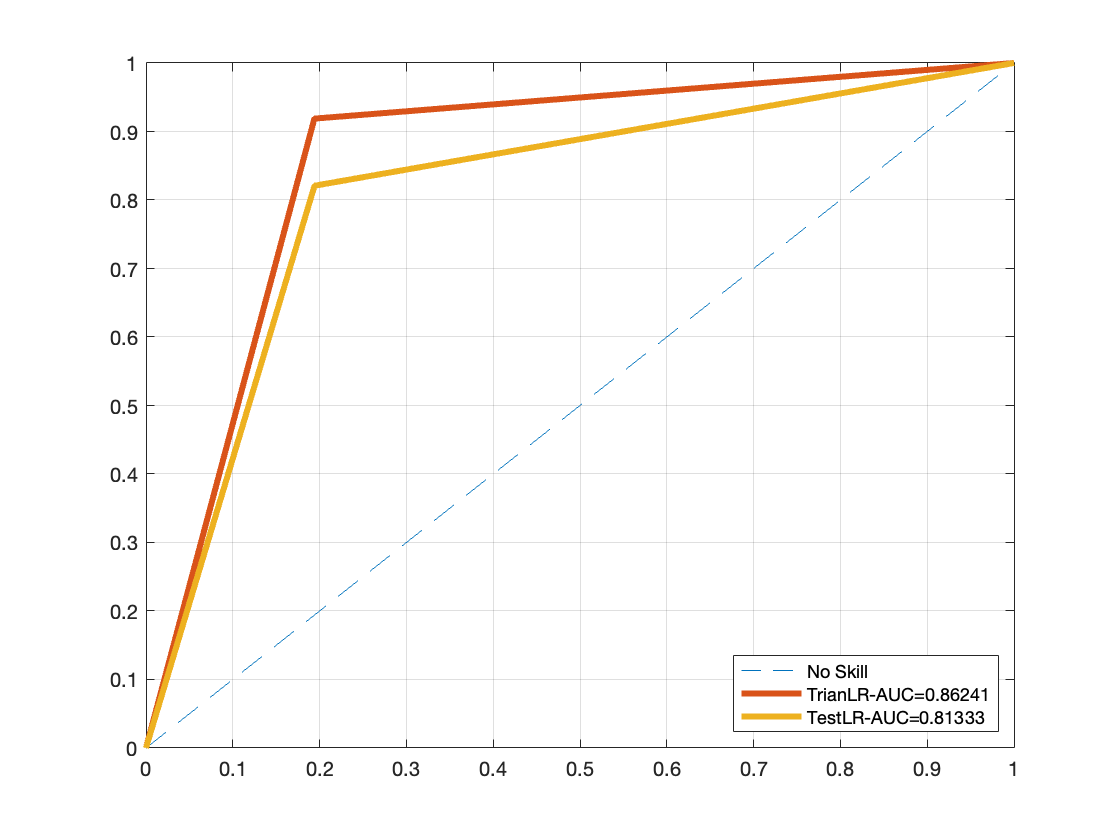

curves = zeros(4,1); labels = cell(4,1);
[LRtrainX,LRtrainY,LRtrainT,LRtrainAUC] = perfcurve(y_train,LRpredYtrain,1);
[LRtestX,LRtestY,LRtestT,LRtestAUC] = perfcurve(y_test,LRpredYtest,1);

figure;
xlabel('False positive rate') 
ylabel('True positive rate')
title('ROC and AUC for Training and Testing Set')
plot([0, 1], [0, 1], "LineStyle","--", 'DisplayName',strcat('No Skill'))
hold on;
plot(LRtrainX,LRtrainY,'LineWidth',3,'DisplayName',strcat('TrianLR-AUC=',num2str(LRtrainAUC)))
hold on;
plot(LRtestX,LRtestY,'LineWidth',3,'DisplayName',strcat('TestLR-AUC=',num2str(LRtestAUC)))
hold off;
grid on
lgd = legend('Location','SE');
lgd.NumColumns = 1;

*Precision-Recall ROC AUC*

And like the ROC AUC, we can calculate the area under the curve as a score and use that score to compare classifiers. In this case, the focus on the minority class makes the Precision-Recall AUC more useful for imbalanced classification problems.

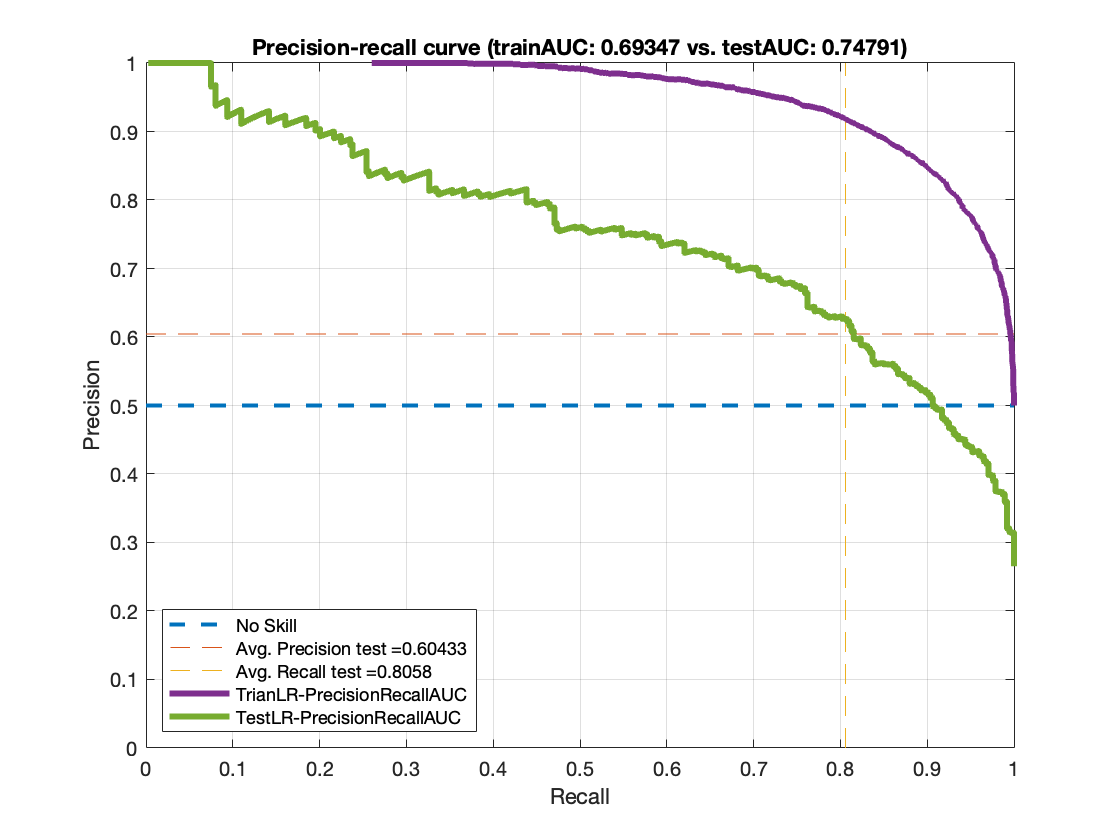

[LRtrainXpr,LRtrainYpr,LRtrainTpr,LRtrainAUCpr]=perfcurve(y_train,abs(LRpredYtrainScore(:,2)),1,  'xCrit', 'reca', 'yCrit', 'prec');
[LRtestXpr,LRtestYpr,LRtestTpr,LRtestAUCpr]=perfcurve(y_test,abs(LRpredYtestScore(:,2)),1,  'xCrit', 'reca', 'yCrit', 'prec');
plot([0, 1], [0.5, 0.5], "LineStyle","--",'Linewidth', 2, 'DisplayName',strcat('No Skill'))
hold on;
plot([0, 1], [LRpre, LRpre], "LineStyle","--", 'Linewidth', 0.2, 'DisplayName',strcat('Avg. Precision test = ', num2str(LRpre)))
hold on;
plot([LRspe, LRspe], [0, 1], "LineStyle","--", 'Linewidth', 0.2, 'DisplayName',strcat('Avg. Recall test = ', num2str(LRspe)))
hold on;
plot(LRtrainXpr,LRtrainYpr,'LineWidth',3,'DisplayName',strcat('TrianLR-PrecisionRecallAUC'))
hold on;
plot(LRtestXpr,LRtestYpr,'LineWidth',3,'DisplayName',strcat('TestLR-PrecisionRecallAUC'))
hold off;
grid on;
xlabel('Recall'); ylabel('Precision')
title(['Precision-recall curve (trainAUC: ' num2str(LRtrainAUCpr), ' vs. ' 'testAUC: ' num2str(LRtestAUCpr) ')'])
lgd = legend('Location','SW');
lgd.NumColumns = 1;

# D. Random Forest Modelling 

### D.1. **Train Bagged Ensemble of Regression Trees - using hyperparameters acquired from home-made grid search**

tic
rng('default')            % For reproducibility
N = size(training,1);
t = templateTree('MaxNumSplits',150,...
    'MinLeafSize',4,...
    'Reproducible',true);
RFmdl = fitcensemble(X_train_unbalanced,y_train_unbalanced, ...
    'Method','Bag', ...
    'Learners',t, ...
    'Prior',[26.5, 73.5], ...
    'Cost',[0 3; 1 0], ...
    "NumLearningCycles",200);
toc

Elapsed time is 3.662535 seconds.


### D.2. Confusion matrix - Training data

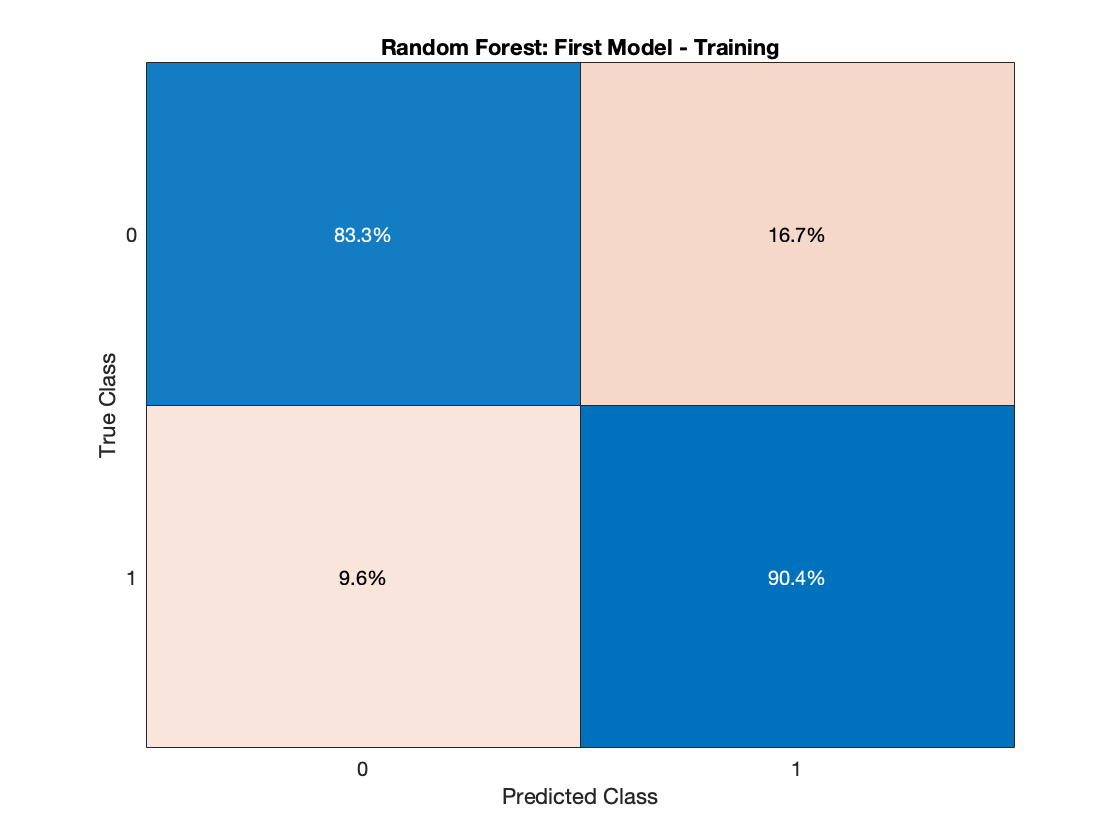

RFpredYtrain = predict(RFmdl, X_train_unbalanced);
confusionchart(y_train_unbalanced,RFpredYtrain, "Normalization","row-normalized" ,...
    "Title",'Random Forest: First Model - Training');

### D.3. Feature importance

Estimate predictor importance measures by permuting out-of-bag observations.

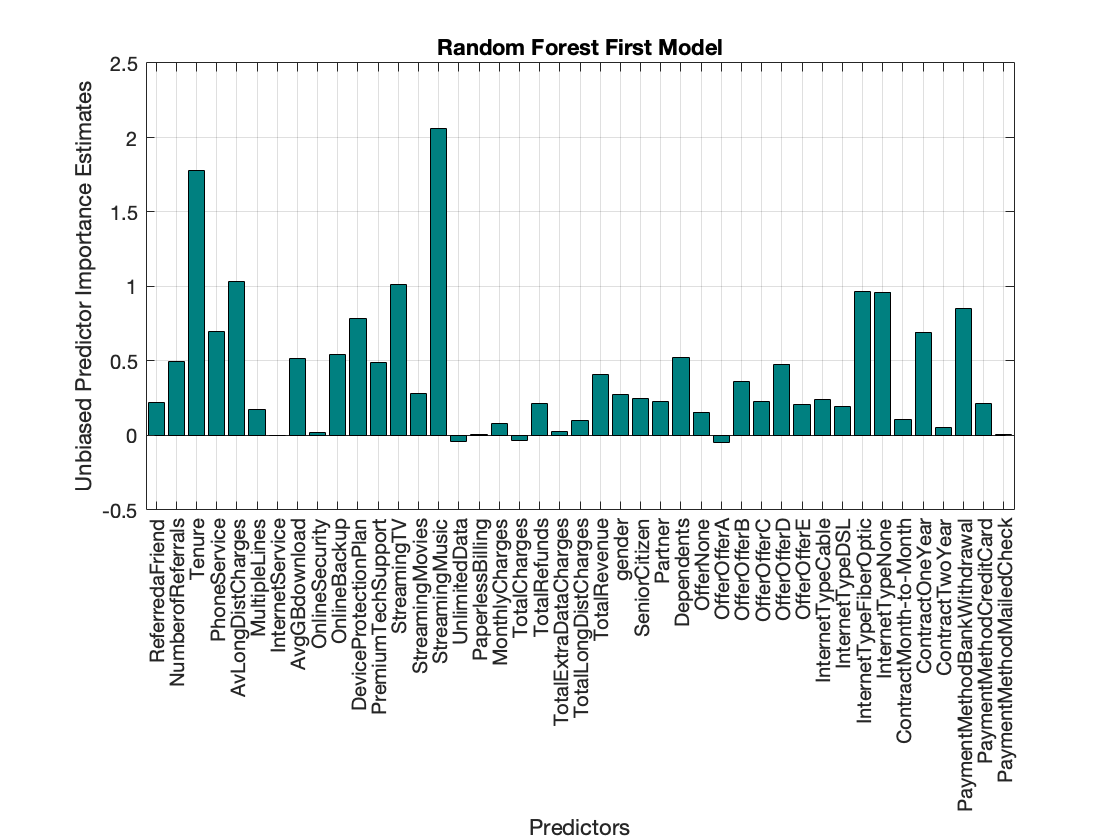

options = statset('UseParallel',true);
imp = oobPermutedPredictorImportance(RFmdl,'Options',options);
figure();
Xnames = categorical(training(:, 1:end-1).Properties.VariableNames);
bar(Xnames,imp,'FaceColor',[0 .5 .5], ...
    'EdgeColor',[0 0 0],'LineWidth',.5);
ylabel('Unbiased Predictor Importance Estimates');
xlabel('Predictors');
title('Random Forest First Model')
set(gca,'xticklabel',Xnames, 'XTickLabelRotation', 90)
ax=gca;
ax.FontSize=10;
grid on

### **D.4. Cross Validation Error**

Generate a 10-fold cross-validated ensemble on training data.

tic
rng('default') % For reproducibility
RFmdlCV = fitcensemble(X_train_unbalanced,y_train_unbalanced, ...
    'Method','Bag', ...
    'Kfold',10, ...
    'Learners',t, ...
    'Prior',[26.5, 73.5], ...
    'Cost',[0 3; 1 0], ...
    "NumLearningCycles",200);
toc

Elapsed time is 27.264279 seconds.


Examine the cross-validation loss as a function of the number of trees in the ensemble.

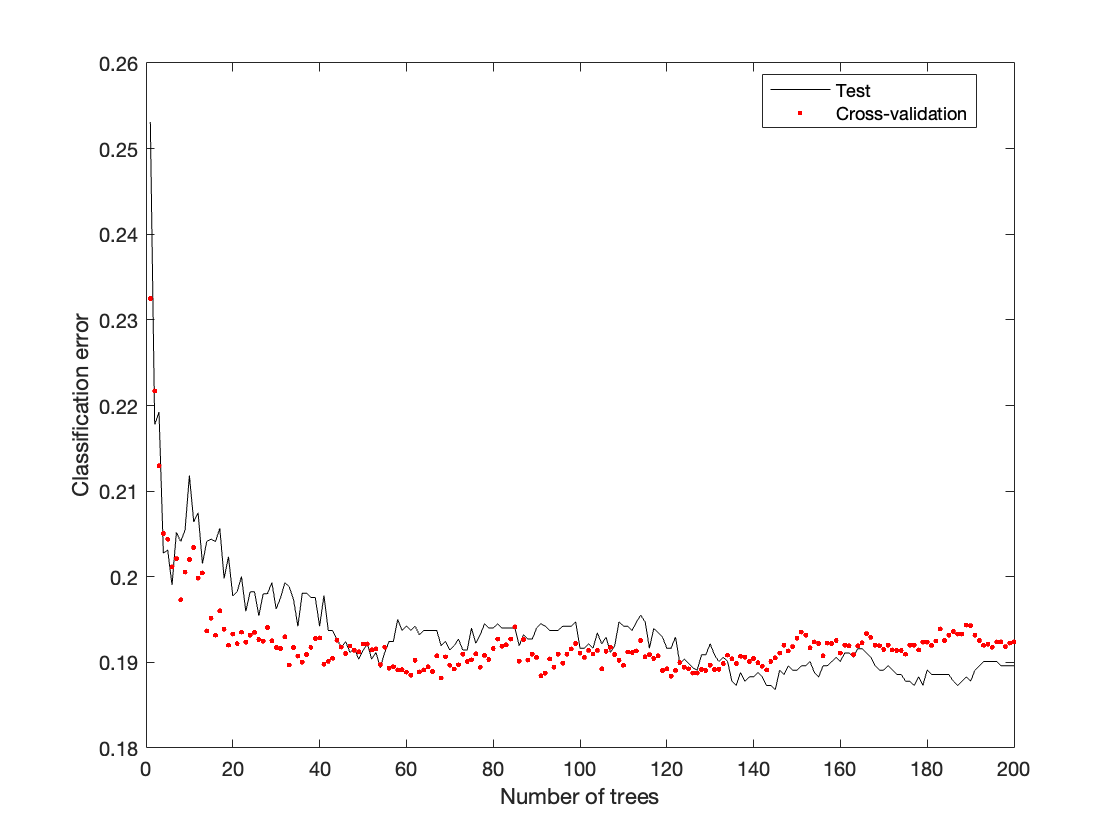

figure;
% plot(loss(RFmdl,X_train_unbalanced,y_train_unbalanced,'mode','cumulative'), 'b')
% hold on;
plot(loss(RFmdl,X_test,y_test,'mode','cumulative'), 'k')
hold on;
plot(kfoldLoss(RFmdlCV,'mode','cumulative'),'r.')
% hold on;
% plot(resubLoss(RFmdl, 'mode', 'cumulative'), 'k--',"LineWidth",2)
hold off;
xlabel('Number of trees')
ylabel('Classification error')
legend('Test', 'Cross-validation','Location','Best')

Cross validating gives comparable estimates to those of the independent set.

### D.5. Optimization of number of trees

rfkfold = kfoldLoss(RFmdlCV, 'mode', 'cumulative');
minErr = min(rfkfold);
minErridx = find(rfkfold==min(rfkfold), 1 );
fprintf('\nMinimum cross validated classification error = %0.5f',minErr)


Minimum cross validated classification error = 0.18818

fprintf('\nOptimal Num. Trees = %d',minErridx);


Optimal Num. Trees = 68

### D.6. Final Random Forest Model

i. Create a predictive random forest based on the optimal hyperparameters and the entire training set.

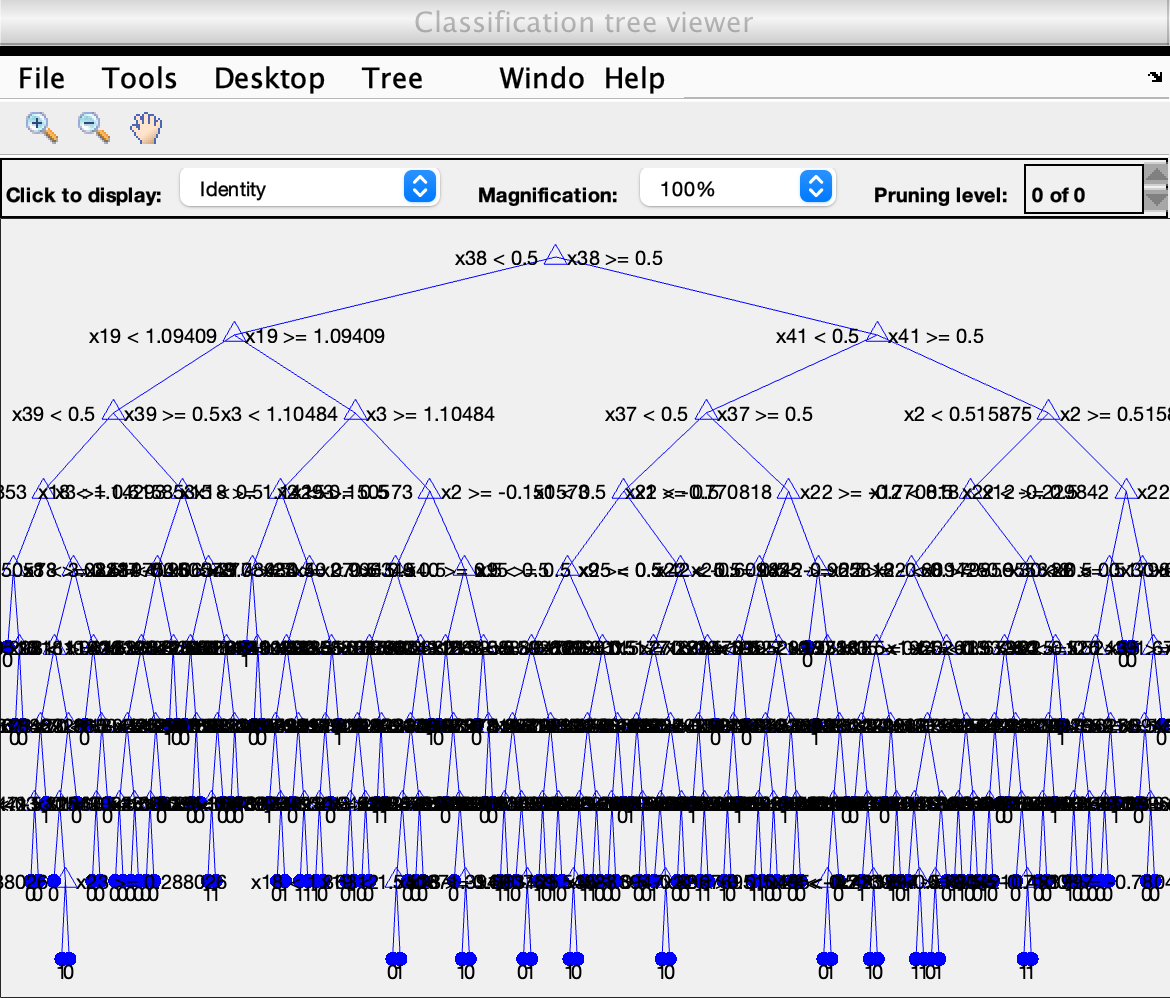

rng('default')
RFmdlFinal = fitcensemble(X_train_unbalanced,y_train_unbalanced, ...
    'Method','Bag', ...
    'NumLearningCycles',minErridx,...
    'Learners',t, ...
    'Prior',[26.5, 73.5], ...
    'Cost',[0 3; 1 0]);
figure;
Tree10 = RFmdlFinal.Trained{10};
view(Tree10,'Mode','graph');

ii. Make predictions with the new model

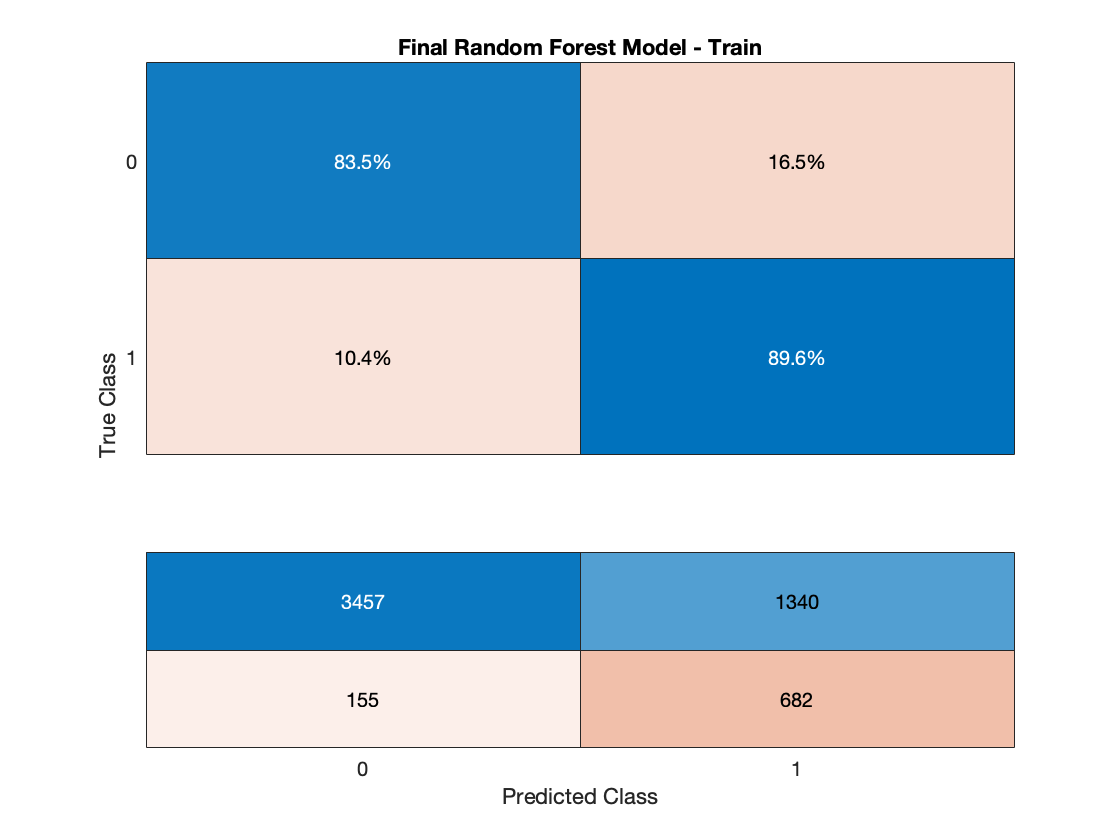

% confusion matrix for training set
[RFpredYtrainFinal, RFpredYtrainScoreFinal] = predict(RFmdlFinal, X_train_unbalanced);
confusionchart(y_train_unbalanced,RFpredYtrainFinal, ...
    'Normalization','row-normalized', ...
    'ColumnSummary',"absolute",...
    'Title','Final Random Forest Model - Train');

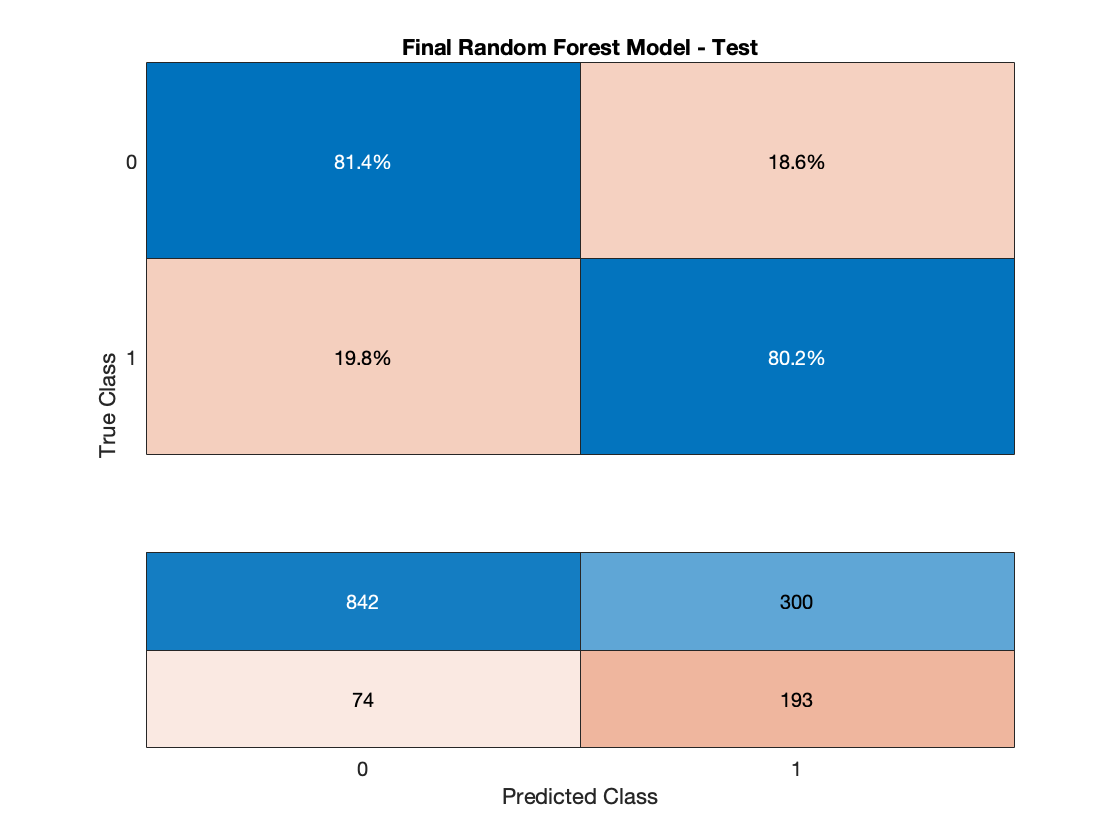

% confusion matrix for validation set
[RFpredYtestFinal,RFpredYtestScoreFinal] = predict(RFmdlFinal, X_test);
confusionchart(y_test,RFpredYtestFinal, ...
    'Normalization','row-normalized', ...
    'ColumnSummary',"absolute",...
    'Title','Final Random Forest Model - Test');

% loss
RFlossFinal = loss(RFmdlFinal, X_test, y_test)

RFlossFinal = 0.1919

**i. Threshold Metrics**                   

                       Predicted Class 1      Predicted Class 2

True Class 1                  TN                            FP

True Class 2                  FN                            TP

RFconfMatFinal = confusionmat(y_test,RFpredYtestFinal)

RFconfMatFinal =    842   193
    74   300


% Accuracy = (TP+TN)/(TP+TN+FP+FN)
RFaccFinal = (RFconfMatFinal(1,1)+RFconfMatFinal(2,2))/sum(sum(RFconfMatFinal))

RFaccFinal = 0.8105

% Sensitivity/Recall = TP/(FN+TP)
RFsenFinal = RFconfMatFinal(2,2)/(RFconfMatFinal(2,1)+RFconfMatFinal(2,2))

RFsenFinal = 0.8021

% Specificity(True Negative Rate) = TN/(TN+FP)
RFspeFinal = RFconfMatFinal(1,1)/(RFconfMatFinal(1,1)+RFconfMatFinal(1,2))

RFspeFinal = 0.8135

% Precision = TP/(TN+TP)
RFpreFinal = RFconfMatFinal(2,2)/(RFconfMatFinal(1,2)+RFconfMatFinal(2,2))  

RFpreFinal = 0.6085

% f1 score
RFf1Final  = 2/(1/RFpreFinal + 1/RFsenFinal)

RFf1Final = 0.6920

% f2 score
RFf2Final = (5*RFpreFinal*RFsenFinal)/(4*RFpreFinal+RFsenFinal)

RFf2Final = 0.7541

% G-Mean
RFgmeanFinal = sqrt(RFsenFinal * RFspeFinal)

RFgmeanFinal = 0.8078

**ii. Ranking metrics**

ROC and AUC

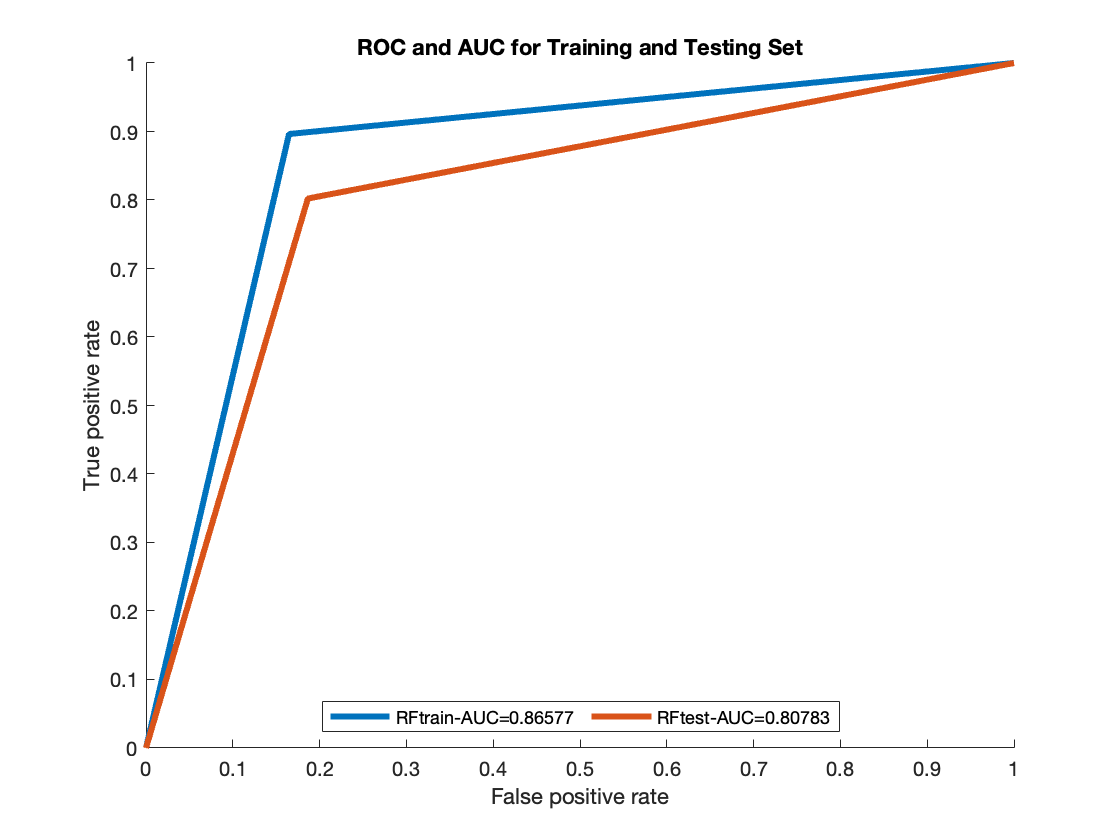

curves = zeros(4,1); labels = cell(4,1);
[RFtrainXfinal,RFtrainYfinal,RFtrainTfinal,RFtrainAUCfinal] = perfcurve(y_train_unbalanced,RFpredYtrainFinal,1);
[RFtestXfinal,RFtestYfinal,RFtestTfinal,RFtestAUCfinal] = perfcurve(y_test,RFpredYtestFinal,1);

figure;
xlabel('False positive rate') 
ylabel('True positive rate')
title('ROC and AUC for Training and Testing Set')

hold on;
plot(RFtrainXfinal,RFtrainYfinal,'LineWidth',3,'DisplayName',strcat('RFtrain-AUC=',num2str(RFtrainAUCfinal)))
plot(RFtestXfinal,RFtestYfinal,'LineWidth',3,'DisplayName',strcat('RFtest-AUC=',num2str(RFtestAUCfinal)))
hold off;
lgd = legend('Location','south');
lgd.NumColumns = 2;

And like the ROC AUC, we can calculate the area under the curve as a score and use that score to compare classifiers. In this case, the focus on the minority class makes the Precision-Recall AUC more useful for imbalanced classification problems.

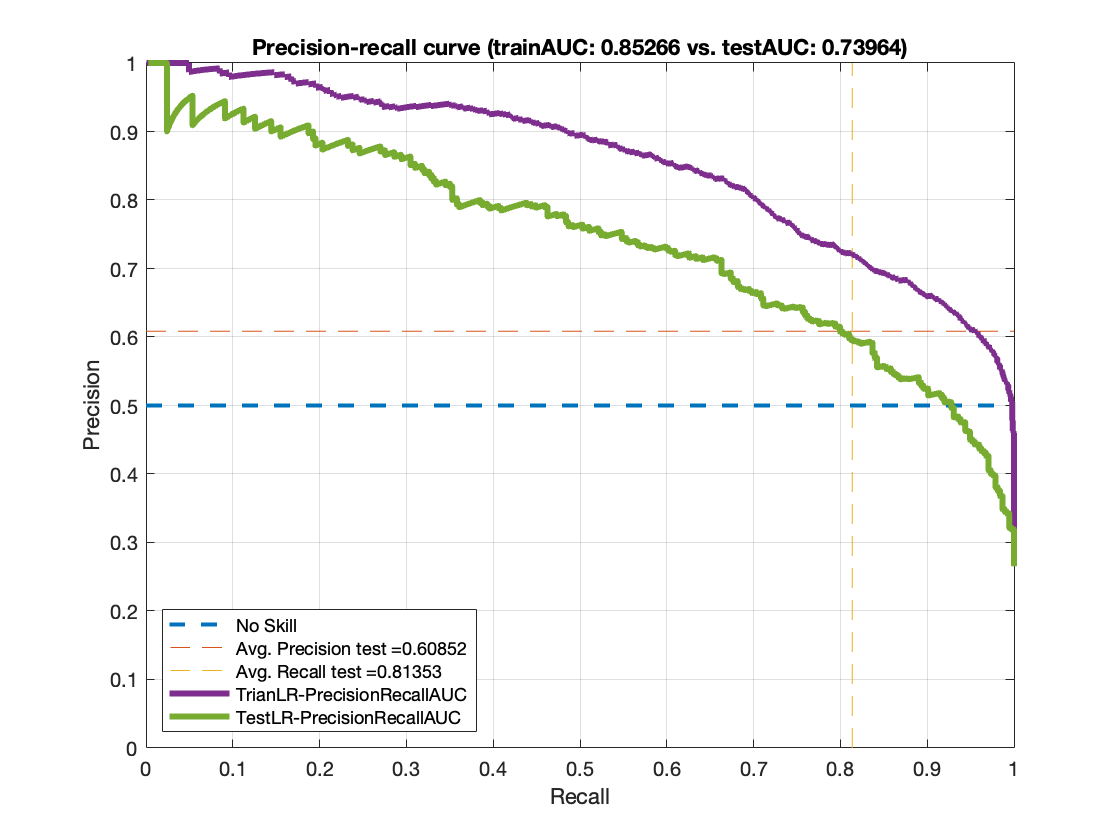

[RFtrainXpr,RFtrainYpr,RFtrainTpr,RFtrainAUCpr]=perfcurve(y_train_unbalanced,abs(RFpredYtrainScoreFinal(:,2)), 1, 'xCrit', 'reca', 'yCrit', 'prec');
[RFtestXpr,RFtestYpr,RFtestTpr,RFtestAUCpr]=perfcurve(y_test,abs(RFpredYtestScoreFinal(:,2)),1,  'xCrit', 'reca', 'yCrit', 'prec');
plot([0, 1], [0.5, 0.5], "LineStyle","--", 'Linewidth', 2, 'DisplayName',strcat('No Skill'))
hold on;
plot([0, 1], [RFpreFinal, RFpreFinal], "LineStyle","--", 'Linewidth', 0.2, 'DisplayName',strcat('Avg. Precision test = ', num2str(RFpreFinal)))
hold on;
plot([RFspeFinal, RFspeFinal], [0, 1], "LineStyle","--", 'Linewidth', 0.2, 'DisplayName',strcat('Avg. Recall test = ', num2str(RFspeFinal)))
hold on;
plot(RFtrainXpr,RFtrainYpr,'LineWidth',3,'DisplayName',strcat('TrianLR-PrecisionRecallAUC'))
hold on;
plot(RFtestXpr,RFtestYpr,'LineWidth',3,'DisplayName',strcat('TestLR-PrecisionRecallAUC'))
hold off;
grid on;
xlabel('Recall'); ylabel('Precision')
title(['Precision-recall curve (trainAUC: ' num2str(RFtrainAUCpr), ' vs. ' 'testAUC: ' num2str(RFtestAUCpr) ')'])
lgd = legend('Location','SW');
lgd.NumColumns = 1;

# F. Comparison of Models (Logistic Regression vs. Random Forest)

### F.1. ROC and AUC Curves

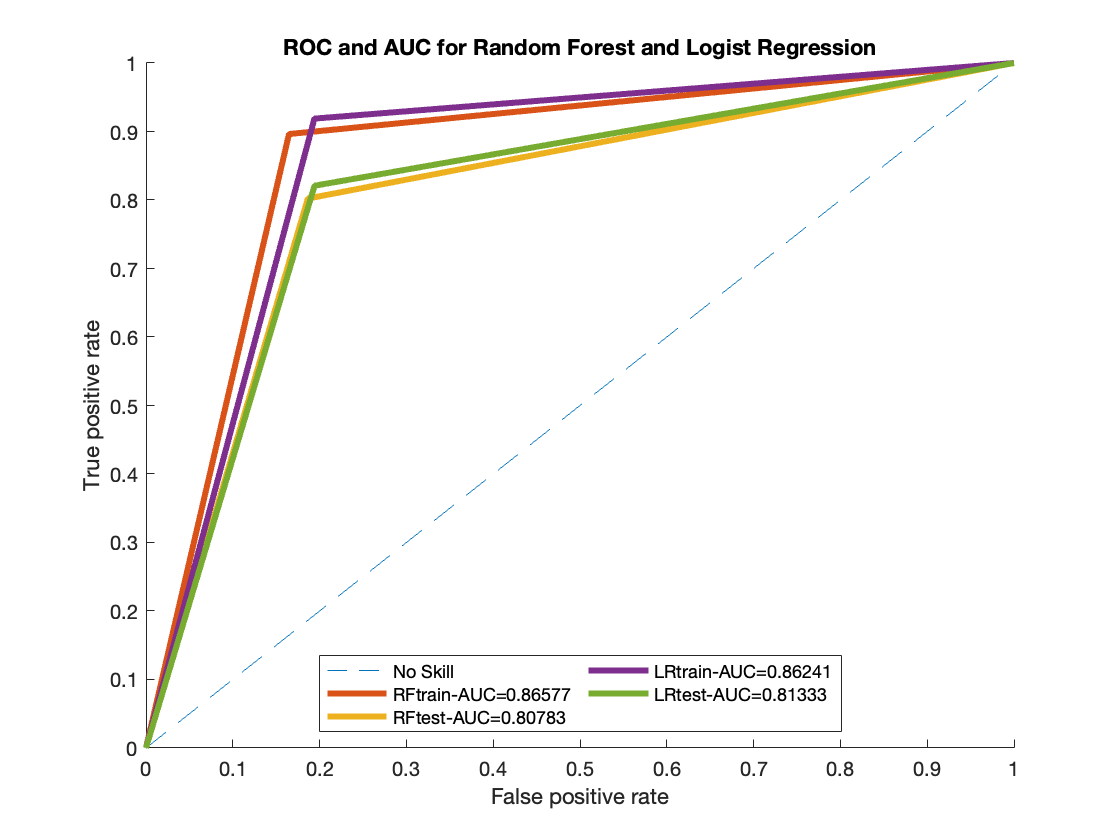

figure;
xlabel('False positive rate') 
ylabel('True positive rate')
title('ROC and AUC for Random Forest and Logist Regression')

hold on;
plot([0, 1], [0, 1], "LineStyle","--", 'DisplayName',strcat('No Skill'))
plot(RFtrainXfinal,RFtrainYfinal,'LineWidth',3,'DisplayName',strcat('RFtrain-AUC=',num2str(RFtrainAUCfinal)))
plot(RFtestXfinal,RFtestYfinal,'LineWidth',3,'DisplayName',strcat('RFtest-AUC=',num2str(RFtestAUCfinal)))
plot(LRtrainX,LRtrainY,'LineWidth',3,'DisplayName',strcat('LRtrain-AUC=',num2str(LRtrainAUC)))
plot(LRtestX,LRtestY,'LineWidth',3,'DisplayName',strcat('LRtest-AUC=',num2str(LRtestAUC)))

hold off
lgd = legend('Location','south');
lgd.NumColumns = 2;

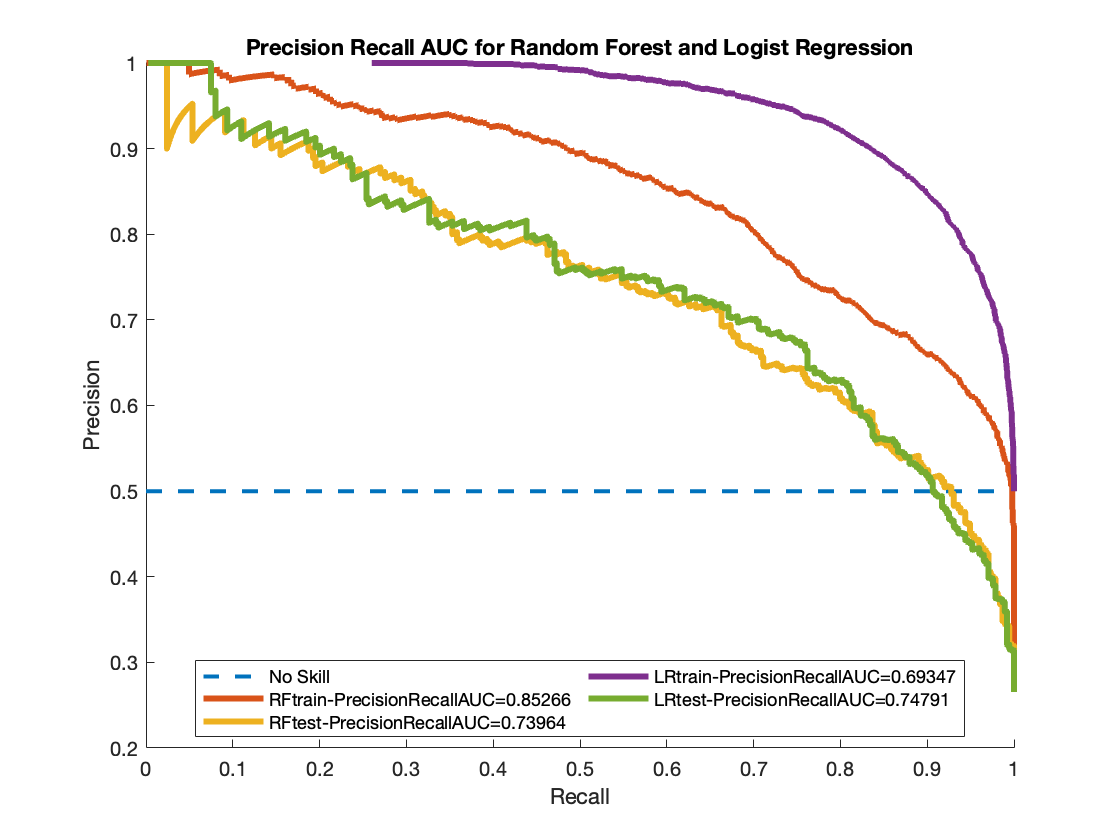

figure;
xlabel('Recall') 
ylabel('Precision')
title('Precision Recall AUC for Random Forest and Logist Regression')
hold on;
plot([0, 1], [0.5, 0.5], "LineStyle","--", 'Linewidth', 2, 'DisplayName',strcat('No Skill'))
plot(RFtrainXpr,RFtrainYpr,'LineWidth',3,'DisplayName',strcat('RFtrain-PrecisionRecallAUC=',num2str(RFtrainAUCpr)))
plot(RFtestXpr,RFtestYpr,'LineWidth',3,'DisplayName',strcat('RFtest-PrecisionRecallAUC=',num2str(RFtestAUCpr)))
plot(LRtrainXpr,LRtrainYpr,'LineWidth',3,'DisplayName',strcat('LRtrain-PrecisionRecallAUC=',num2str(LRtrainAUCpr)))
plot(LRtestXpr,LRtestYpr,'LineWidth',3,'DisplayName',strcat('LRtest-PrecisionRecallAUC=',num2str(LRtestAUCpr)))
hold off;
lgd = legend('Location','best');
lgd.NumColumns = 2;

### F.2. Performance measures

modelName = {'Logistic Regression', 'Random Forest'};
performanceMeasures = {'Accuracy', 'Sensitivity/Recall', 'Specificity/TNR',... 
    'Precision',  'f1-score', 'f2-score','G-Mean','AUC', 'Precision-Recall AUC'};
res = [LRacc,RFaccFinal;
       LRsen,RFsenFinal;
       LRspe,RFspeFinal;
       LRpre,RFpreFinal;
       LRf1, RFf1Final;
       LRf2,RFf1Final;
       LRgmean, RFgmeanFinal;
       LRtestAUC(1)*100, RFtestAUCfinal(1)*100;
       LRtestAUCpr(1)*100, RFtestAUCpr(1)*100];
restable= array2table(res,'RowNames',performanceMeasures,'VariableNames',modelName);
disp(restable);

                            Logistic Regression    Random Forest
                            ___________________    _____________
    Accuracy                      0.80979              0.8105   
    Sensitivity/Recall            0.82086             0.80214   
    Specificity/TNR                0.8058             0.81353   
    Precision                     0.60433             0.60852   
    f1-score                      0.69615             0.69204   
    f2-score                      0.76597             0.69204   
    G-Mean                        0.81329             0.80781   
    AUC                            81.333              80.783   
    Precision-Recall AUC           74.791              73.964   


The most important performance measures are Sensitivity/Recall (how many of the clients who actually leave were detected by the model) and precision (how many of the clients identified by the model actually left). Both models provide comparative results, Logistic Regression being slightly better with the much better  F2 Score and Recall. 

Logistic regression performs better when the number of noise variables is less than or equal to the number of explanatory variables and the random forest has a higher true and false positive rate as the number of explanatory variables increases in a dataset.

### F.3. Feature Importance 

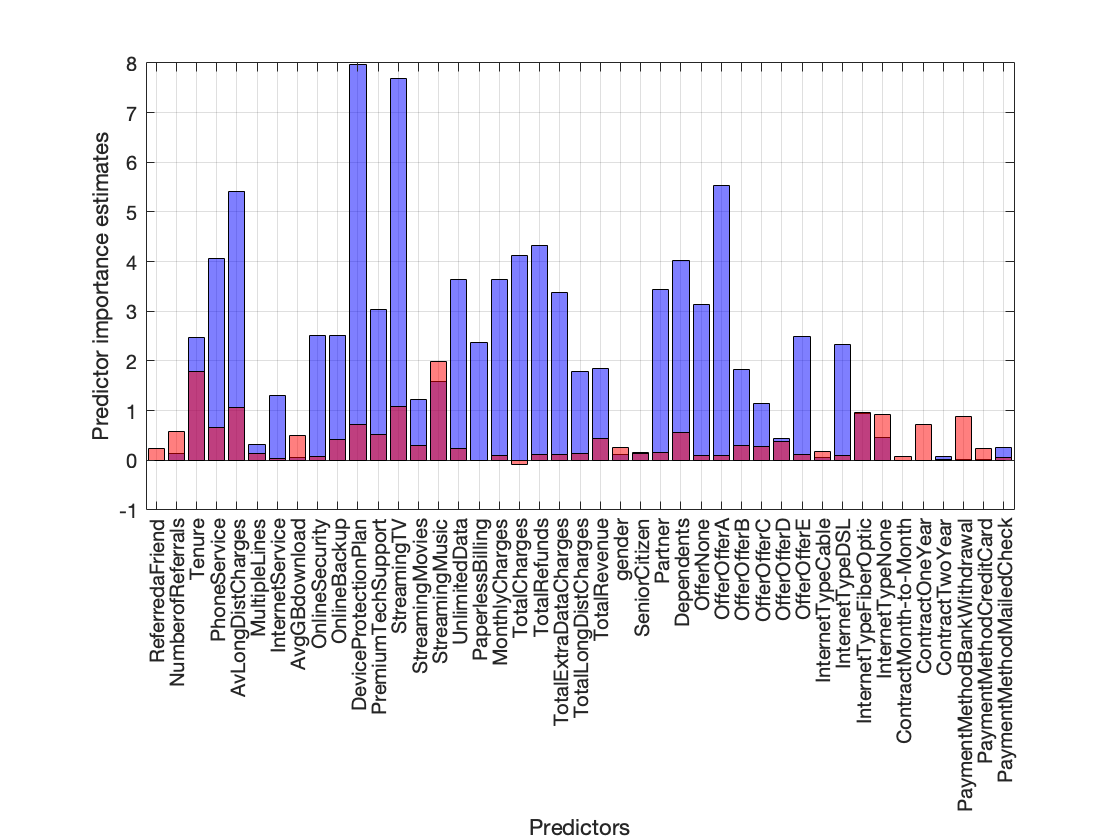

figure;
options = statset('UseParallel',true);
Xnames = categorical(training(:, 1:end-1).Properties.VariableNames);
imp = oobPermutedPredictorImportance(RFmdl,'Options',options);
abs_coef = abs(B(:,idxLambda1SE));
b1 = bar(Xnames,abs_coef, 'FaceColor',[0 0 1], ...
     'EdgeColor',[0 0 0],'LineWidth',.5);
hold on;
b2 = bar(Xnames,imp,'FaceColor',[1 0 0], ...
     'EdgeColor',[0 0 0],'LineWidth',.5);
hold off;
alpha(b1, 0.5);
alpha(b2, 0.5);
ylabel('Predictor importance estimates');
xlabel('Predictors');
set(gca,'xticklabel',Xnames, 'XTickLabelRotation', 90)
ax=gca;
ax.FontSize=10;
grid on

### F.4. Accuracy

% accuracy of Logistic Regression
LR_matches = 0;
for i = 1:size(LRpredYtest,1)
    if LRpredYtest(i)==y_test(i)
        LR_matches = LR_matches + 1;
    end
end
LR_accuracy = LR_matches/size(LRpredYtest,1)

LR_accuracy = 0.8098

% accuracy of Random forest
RF_matches = 0;
for i = 1:size(RFpredYtestFinal,1)
    if RFpredYtestFinal(i)==y_test(i)
        RF_matches = RF_matches + 1;
    end
end
RF_accuracy = RF_matches/size(RFpredYtestFinal,1)

RF_accuracy = 0.8105

% compare accuracies of the two models
[h,p,LR_classloss,R_classloss] = testcholdout(LRpredYtest, RFpredYtestFinal,y_test)

h = logical
   0

p = 0.9273

LR_classloss = 0.1902

R_classloss = 0.1895

Comparing the two models, one can see that the accuracies and classification loss  of both models are very close to each other

`h = 0` indicates to not reject the null hypothesis that the two models have equal predictive accuracies.

`h = 1` indicates to reject the null hypothesis that the two models have differing predictive accuracies.

% commented out to avoid repeated savings
% save("finalModels", "LRmdl", "RFmdlFinal", "X_test", "y_test") 